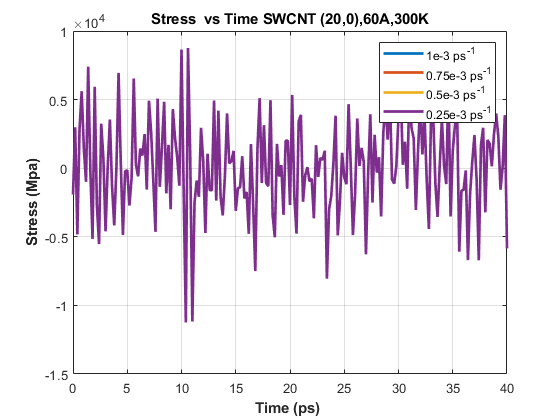

 %%%swcnt
clc
clear all
close all


%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.1.
CNT200Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.1.Equi.txt','r');
CNT200Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.1.Deform.txt','r');
CNT200Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.75.Equi.txt','r');
CNT200Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.75.Deform.txt','r');
CNT200Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.5.Equi.txt','r');
CNT200Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.5.Deform.txt','r');
CNT200Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.25.Equi.txt','r');
CNT200Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.25.Deform.txt','r'); 
CNT200Equ01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.01.Equi.txt','r');
CNT200Def01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.01.Deform.txt','r');

EquCNT2001 = cell2mat(textscan(CNT200Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT2001 =cell2mat(textscan(CNT200Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT20075 = cell2mat(textscan(CNT200Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT20075 =cell2mat(textscan(CNT200Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT2005 = cell2mat(textscan(CNT200Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT2005 =cell2mat(textscan(CNT200Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT20025 = cell2mat(textscan(CNT200Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT20025 =cell2mat(textscan(CNT200Def25,'%f%f%f%f%f%f','headerlines',1));
EquCNT20001 = cell2mat(textscan(CNT200Equ01,'%f%f%f%f%f','headerlines',1));
DefCNT20001 =cell2mat(textscan(CNT200Def01,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT200Equ1);
fclose(CNT200Def1);
fclose(CNT200Equ75);
fclose(CNT200Def75);
fclose(CNT200Equ5);
fclose(CNT200Def5);
fclose(CNT200Equ25);
fclose(CNT200Def25);
fclose(CNT200Equ01);
fclose(CNT200Def01);
%%%%finding peaaks

figure(1)  %%% equilibtration...stress vs time
plot(EquCNT2001(:,1),EquCNT2001(:,5),"LineWidth",2); 
hold on
plot(EquCNT20075(:,1),EquCNT20075(:,5),"LineWidth",2); 
hold on
plot(EquCNT2005(:,1),EquCNT2005(:,5),"LineWidth",2); 
hold on
plot(EquCNT20025(:,1),EquCNT20025(:,5),"LineWidth",2); 
hold on



title('Stress  vs Time SWCNT (20,0),60A,300K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on

hold off

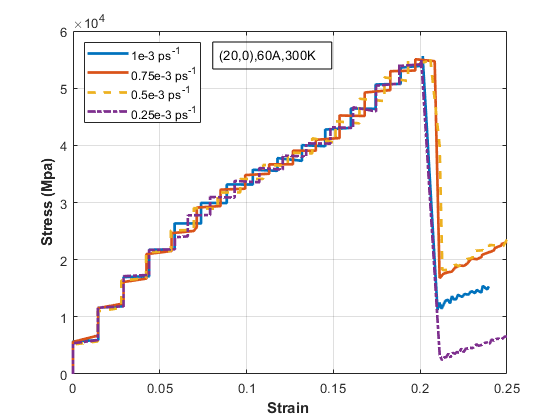

%%%%finding Sut...and yield strain
[Sut1,In1]= max(DefCNT2001(:,6));Ys1=DefCNT2001(In1,5);
[Sut2,In2]= max(DefCNT20075(:,6));Ys2=DefCNT20075(In2,5);
[Sut3,In3]= max(DefCNT2005(:,6));Ys3=DefCNT2005(In3,5);
[Sut4,In4]= max(DefCNT20025(:,6));Ys4=DefCNT20025(In4,5);
Sut_300= [Sut1 Sut2 Sut3 Sut4]'*1e-3;  % in Gpa
Ys_300= [Ys1 Ys2 Ys3 Ys4]';  % yield strain

figure(2);   %deformation
plot(DefCNT2001(:,5),DefCNT2001(:,6),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT20075(:,5),DefCNT20075(:,6),"LineWidth",2);
hold on
plot(DefCNT2005(:,5),DefCNT2005(:,6),'--',"LineWidth",2);
hold on
plot(DefCNT20025(:,5),DefCNT20025(:,6),'-.',"LineWidth",2);
hold on



xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','Location','northwest')
grid on
xlim([0 0.25])
ylim([0 6]*1e4)
annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(20,0),60A,300K",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress_vs_Strain200300K.jpg')
 hold off

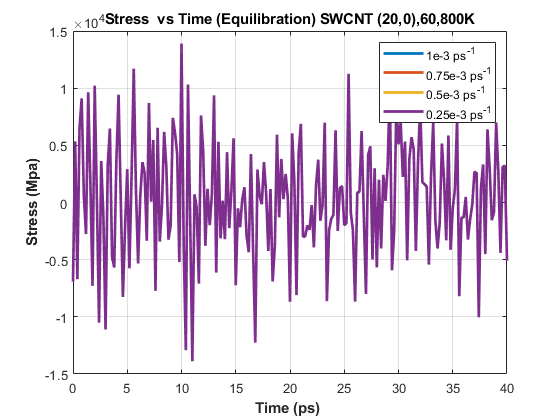



%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K
CNT200Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.1.Equi.txt','r');
CNT200Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.1.Deform.txt','r');
CNT200Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.75.Equi.txt','r');
CNT200Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.75.Deform.txt','r');
CNT200Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.5.Equi.txt','r');
CNT200Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.5.Deform.txt','r');
CNT200Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.25.Equi.txt','r');
CNT200Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.25.Deform.txt','r');
CNT200Equ01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.01.Equi.txt','r');
CNT200Def01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.01.Deform.txt','r');

EquCNT2001 = cell2mat(textscan(CNT200Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT2001 =cell2mat(textscan(CNT200Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT20075 = cell2mat(textscan(CNT200Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT20075 =cell2mat(textscan(CNT200Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT2005 = cell2mat(textscan(CNT200Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT2005 =cell2mat(textscan(CNT200Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT20025 = cell2mat(textscan(CNT200Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT20025 =cell2mat(textscan(CNT200Def25,'%f%f%f%f%f%f','headerlines',1));
EquCNT20001 = cell2mat(textscan(CNT200Equ01,'%f%f%f%f%f','headerlines',1));
DefCNT20001 =cell2mat(textscan(CNT200Def01,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT200Equ1);
fclose(CNT200Def1);
fclose(CNT200Equ75);
fclose(CNT200Def75);
fclose(CNT200Equ5);
fclose(CNT200Def5);
fclose(CNT200Equ25);
fclose(CNT200Def25);
fclose(CNT200Equ01);
fclose(CNT200Def01);

figure(3)  %%% equilibtration...stress vs time
plot(EquCNT2001(:,1),EquCNT2001(:,5),"LineWidth",2); 
hold on
plot(EquCNT20075(:,1),EquCNT20075(:,5),"LineWidth",2); 
hold on
plot(EquCNT2005(:,1),EquCNT2005(:,5),"LineWidth",2); 
hold on
plot(EquCNT20025(:,1),EquCNT20025(:,5),"LineWidth",2); 
hold on

title('Stress  vs Time (Equilibration) SWCNT (20,0),60,800K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
hold off

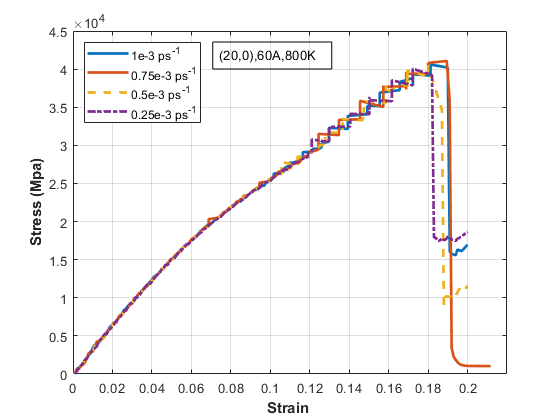

%%%%finding Sut...and yield strain
[Sut1,In1]= max(DefCNT2001(:,6));Ys1=DefCNT2001(In1,5);
[Sut2,In2]= max(DefCNT20075(:,6));Ys2=DefCNT20075(In2,5);
[Sut3,In3]= max(DefCNT2005(:,6));Ys3=DefCNT2005(In3,5);
[Sut4,In4]= max(DefCNT20025(:,6));Ys4=DefCNT20025(In4,5);
Sut_800= [Sut1 Sut2 Sut3 Sut4]'*1e-3;  % in Gpa
Ys_800= [Ys1 Ys2 Ys3 Ys4]';  % yield strain

figure(4);   %deformation
plot(DefCNT2001(:,5),DefCNT2001(:,6),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT20075(:,5),DefCNT20075(:,6),"LineWidth",2);
hold on
plot(DefCNT2005(:,5),DefCNT2005(:,6),'--',"LineWidth",2);
hold on
plot(DefCNT20025(:,5),DefCNT20025(:,6),'-.',"LineWidth",2);
hold on



xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','Location','northwest')
grid on
xlim([0 0.22])
ylim([0 4.5]*1e4)
annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(20,0),60A,800K",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress_vs_Strain200800K.jpg')
hold off

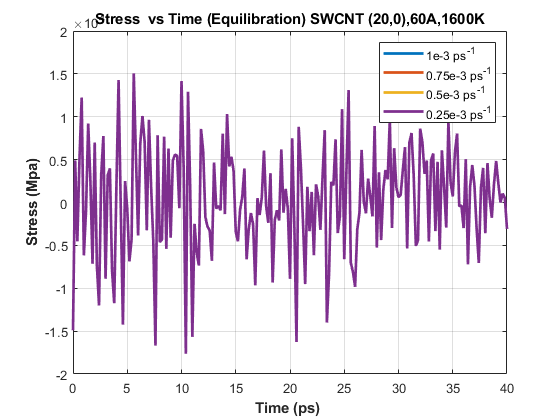


%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1600K
CNT200Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1600K.1.Equi.txt','r');
CNT200Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1600K.1.Deform.txt','r');
CNT200Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1600K.75.Equi.txt','r');
CNT200Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1600K.75.Deform.txt','r');
CNT200Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1600K.5.Equi.txt','r');
CNT200Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1600K.5.Deform.txt','r');
CNT200Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1600K.25.Equi.txt','r');
CNT200Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1600K.25.Deform.txt','r');
CNT200Equ01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1600K.01.Equi.txt','r');
CNT200Def01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1600K.01.Deform.txt','r');


EquCNT2001 = cell2mat(textscan(CNT200Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT2001 =cell2mat(textscan(CNT200Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT20075 = cell2mat(textscan(CNT200Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT20075 =cell2mat(textscan(CNT200Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT2005 = cell2mat(textscan(CNT200Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT2005 =cell2mat(textscan(CNT200Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT20025 = cell2mat(textscan(CNT200Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT20025 =cell2mat(textscan(CNT200Def25,'%f%f%f%f%f%f','headerlines',1));
EquCNT20001 =cell2mat(textscan(CNT200Equ01,'%f%f%f%f%f','headerlines',1));
DefCNT20001 =cell2mat(textscan(CNT200Def01,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT200Equ1);
fclose(CNT200Def1);
fclose(CNT200Equ75);
fclose(CNT200Def75);
fclose(CNT200Equ5);
fclose(CNT200Def5);
fclose(CNT200Equ25);
fclose(CNT200Def25);
fclose(CNT200Equ01);
fclose(CNT200Def01);

figure(5)  %%% equilibtration...stress vs time
plot(EquCNT2001(:,1),EquCNT2001(:,5),"LineWidth",2); 
hold on
plot(EquCNT20075(:,1),EquCNT20075(:,5),"LineWidth",2); 
hold on
plot(EquCNT2005(:,1),EquCNT2005(:,5),"LineWidth",2); 
hold on
plot(EquCNT20025(:,1),EquCNT20025(:,5),"LineWidth",2); 
hold on

title('Stress  vs Time (Equilibration) SWCNT (20,0),60A,1600K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
hold off

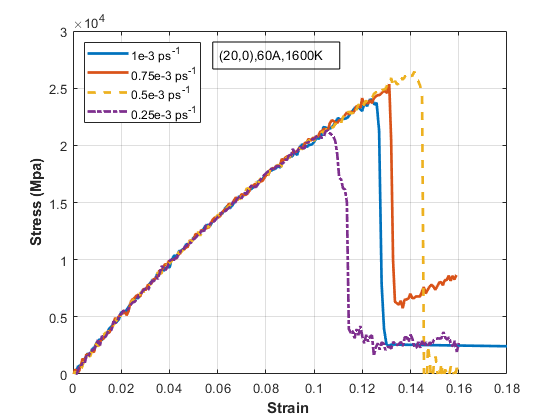

%%%%finding Sut...and yield strain
[Sut1,In1]= max(DefCNT2001(:,6));Ys1=DefCNT2001(In1,5);
[Sut2,In2]= max(DefCNT20075(:,6));Ys2=DefCNT20075(In2,5);
[Sut3,In3]= max(DefCNT2005(:,6));Ys3=DefCNT2005(In3,5);
[Sut4,In4]= max(DefCNT20025(:,6));Ys4=DefCNT20025(In4,5);
Sut_1600= [Sut1 Sut2 Sut3 Sut4]'*1e-3;  % in Gpa
Ys_1600= [Ys1 Ys2 Ys3 Ys4]';  % yield strain

figure(6);   %deformation
plot(DefCNT2001(:,5),DefCNT2001(:,6),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT20075(:,5),DefCNT20075(:,6),"LineWidth",2);
hold on
plot(DefCNT2005(:,5),DefCNT2005(:,6),'--',"LineWidth",2);
hold on
plot(DefCNT20025(:,5),DefCNT20025(:,6),'-.',"LineWidth",2);
hold on



xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','Location','northwest')
grid on
xlim([0 0.18])
ylim([0 3]*1e4)
annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(20,0),60A,1600K",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress_vs_Strain2001600K.jpg')
hold off

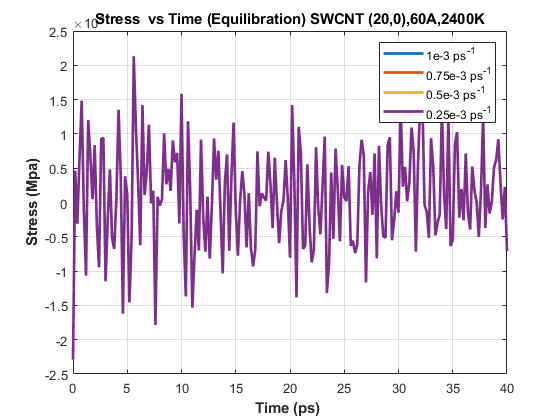

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K

%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K
CNT200Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.1.Equi.txt','r');
CNT200Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.1.Deform.txt','r');
CNT200Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.75.Equi.txt','r');
CNT200Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.75.Deform.txt','r');
CNT200Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.5.Equi.txt','r');
CNT200Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.5.Deform.txt','r');
CNT200Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.25.Equi.txt','r');
CNT200Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.25.Deform.txt','r');
CNT200Equ01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.01.Equi.txt','r');
CNT200Def01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.01.Deform.txt','r');

EquCNT2001 = cell2mat(textscan(CNT200Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT2001 =cell2mat(textscan(CNT200Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT20075 = cell2mat(textscan(CNT200Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT20075 =cell2mat(textscan(CNT200Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT2005 = cell2mat(textscan(CNT200Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT2005 =cell2mat(textscan(CNT200Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT20025 = cell2mat(textscan(CNT200Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT20025 =cell2mat(textscan(CNT200Def25,'%f%f%f%f%f%f','headerlines',1));
EquCNT20001 = cell2mat(textscan(CNT200Equ01,'%f%f%f%f%f','headerlines',1));
DefCNT20001 =cell2mat(textscan(CNT200Def01,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT200Equ1);
fclose(CNT200Def1);
fclose(CNT200Equ75);
fclose(CNT200Def75);
fclose(CNT200Equ5);
fclose(CNT200Def5);
fclose(CNT200Equ25);
fclose(CNT200Def25);
fclose(CNT200Equ01);
fclose(CNT200Def01);

figure(7)  %%% equilibtration...stress vs time
plot(EquCNT2001(:,1),EquCNT2001(:,5),"LineWidth",2); 
hold on
plot(EquCNT20075(:,1),EquCNT20075(:,5),"LineWidth",2); 
hold on
plot(EquCNT2005(:,1),EquCNT2005(:,5),"LineWidth",2); 
hold on
plot(EquCNT20025(:,1),EquCNT20025(:,5),"LineWidth",2); 


title('Stress  vs Time (Equilibration) SWCNT (20,0),60A,2400K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
hold off

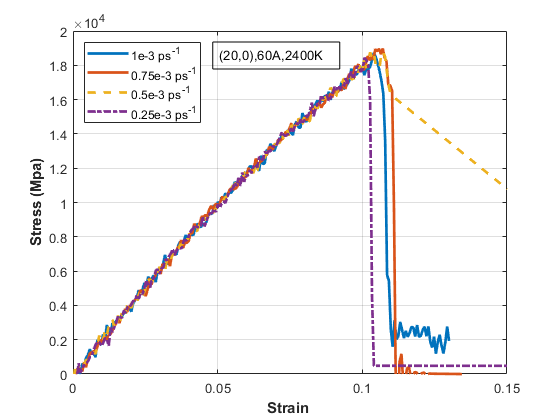

%%%%finding Sut...and yield strain
[Sut1,In1]= max(DefCNT2001(:,6));Ys1=DefCNT2001(In1,5);
[Sut2,In2]= max(DefCNT20075(:,6));Ys2=DefCNT20075(In2,5);
[Sut3,In3]= max(DefCNT2005(:,6));Ys3=DefCNT2005(In3,5);
[Sut4,In4]= max(DefCNT20025(:,6));Ys4=DefCNT20025(In4,5);
Sut_2400= [Sut1 Sut2 Sut3 Sut4]'*1e-3;  % in Gpa
Ys_2400= [Ys1 Ys2 Ys3 Ys4]';  % yield strain

Ys_200= [Ys_300,Ys_800,Ys_1600,Ys_2400];     %yield strain
Sut_200= [Sut_300,Sut_800,Sut_1600,Sut_2400] ;      % young modulus (10,0)
writematrix(Sut_200,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\Sut_200.txt','Delimiter','tab')
writematrix(Ys_200,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\Ys_200.txt','Delimiter','tab')


figure(8);   %deformation
plot(DefCNT2001(:,5),DefCNT2001(:,6),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT20075(:,5),DefCNT20075(:,6),"LineWidth",2);
hold on
plot(DefCNT2005(:,5),DefCNT2005(:,6),'--',"LineWidth",2);
hold on
plot(DefCNT20025(:,5),DefCNT20025(:,6),'-.',"LineWidth",2);
hold on



xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','Location','northwest')
grid on
xlim([0 0.15])
ylim([0 2]*1e4)
annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(20,0),60A,2400K",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress_vs_Strain2002400K.jpg')
hold off